# Control Theory

# Laboratory 1

Mikołaj Suchoń and Witold Surdej

## Exercise 1

a)

generate tf with no zeros and 10 equally spaced poles

Z=[];
K=1;
[~,P]=geteqpols(10);

generate tf with no zeros and 5 equally spaced poles in LHP

P2=P(4:8);
sys = zpk(Z,P2,K);

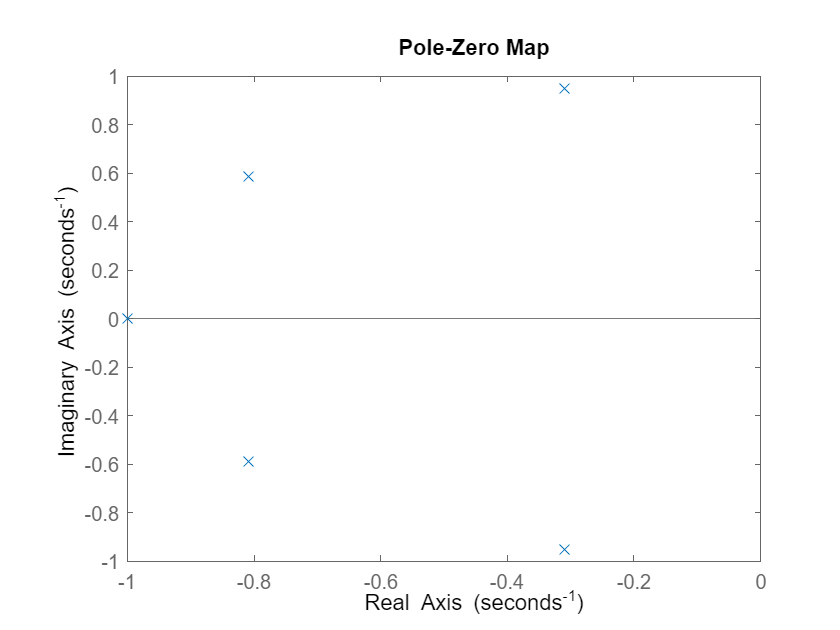

pzmap(sys)

b)

computing step response

dat=stepinfo(sys)

dat = struct with fields:
         RiseTime: 2.5633 + 0.0000i
    TransientTime: 10.8386 + 0.0000i
     SettlingTime: 10.8386 + 0.0000i
      SettlingMin: 0.9090 + 0.0000i
      SettlingMax: 1.1277 + 0.0000i
        Overshoot: 0
       Undershoot: 0
             Peak: 1.1277
         PeakTime: 6.3551


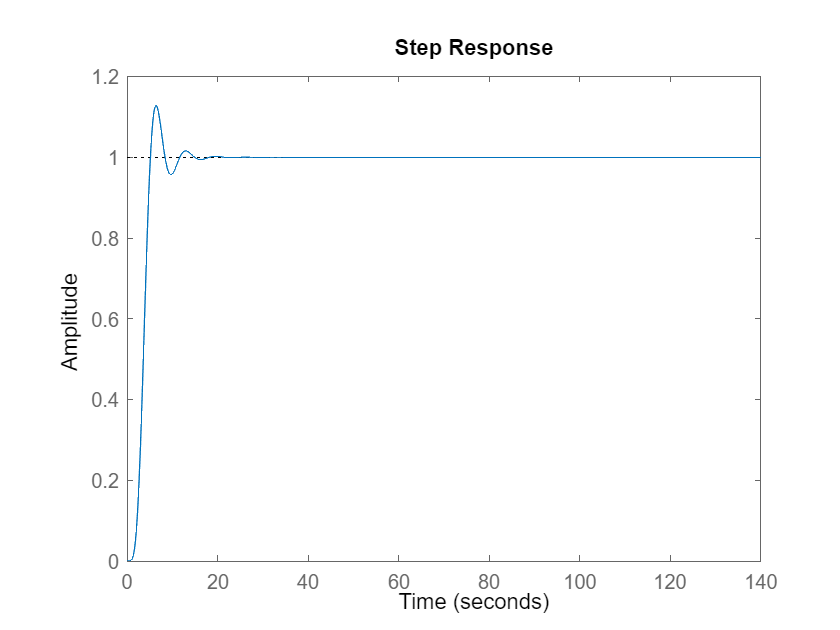

step(sys)

From plot:

t2p,%overshoot,rise time, settling time

datp(1).t2p=6.24;
datp(1).ov=(1.13-1)*100;
datp(1).rt=5.07;
datp(1).st=7.7;


c)

repeating a) and b) for 6 & 14 poles

[~,P2]=geteqpols(6);

[~,P3]=geteqpols(14);


P2=P2(3:5);
sys2 = zpk(Z,P2,K);

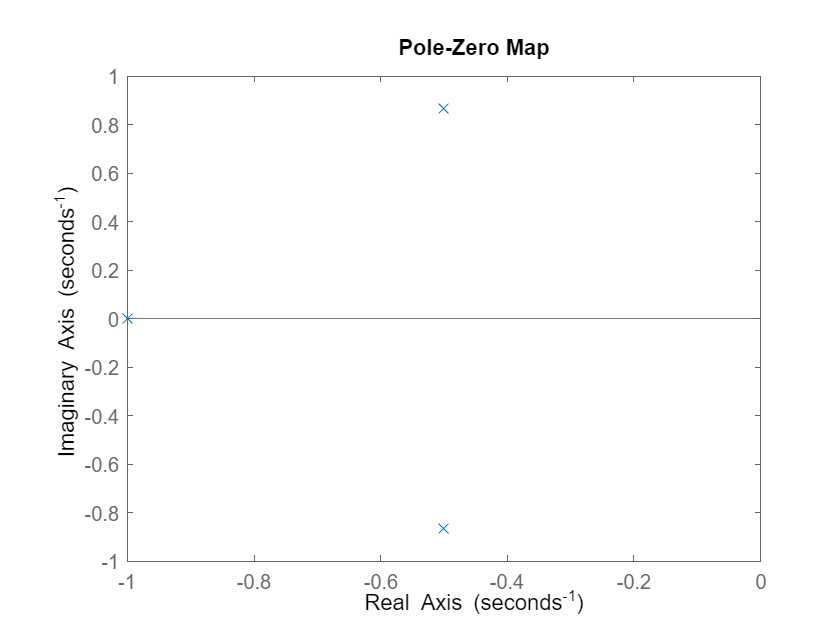

pzmap(sys2)


dat2=stepinfo(sys2)

dat2 = struct with fields:
         RiseTime: 2.2911 - 0.0000i
    TransientTime: 6.6376 + 0.0000i
     SettlingTime: 6.6376 + 0.0000i
      SettlingMin: 0.9050 + 0.0000i
      SettlingMax: 1.0814 + 0.0000i
        Overshoot: 0
       Undershoot: 0
             Peak: 1.0814
         PeakTime: 4.8815


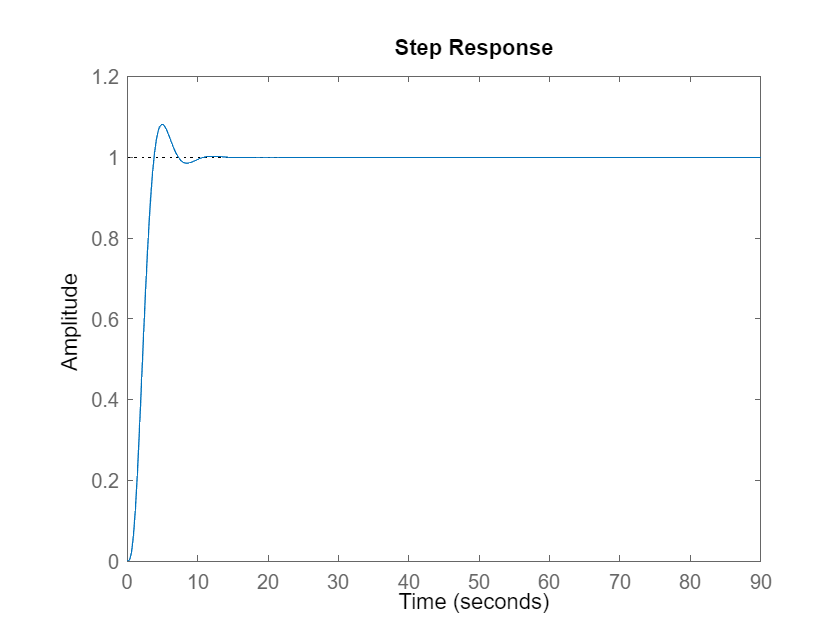

step(sys2)

From plot:

t2p,%overshoot,rise time, settling time

datp(2).t2p=4.91;
datp(2).ov=(1.08-1)*100;
datp(2).rt=3.78;
datp(2).st=6;

P3=P3(5:11);
sys3 = zpk(Z,P3,K);

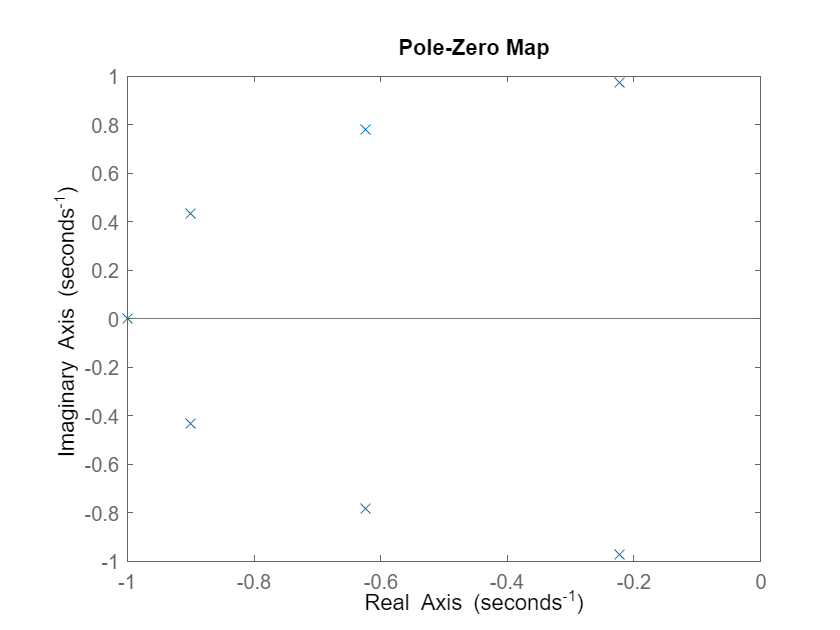

pzmap(sys3)


dat3=stepinfo(sys3)

dat3 = struct with fields:
         RiseTime: 2.7880 - 0.0000i
    TransientTime: 15.2063 + 0.0000i
     SettlingTime: 15.2063 + 0.0000i
      SettlingMin: 0.9046 + 0.0000i
      SettlingMax: 1.1541 + 0.0000i
        Overshoot: 0
       Undershoot: 0
             Peak: 1.1541
         PeakTime: 7.7554


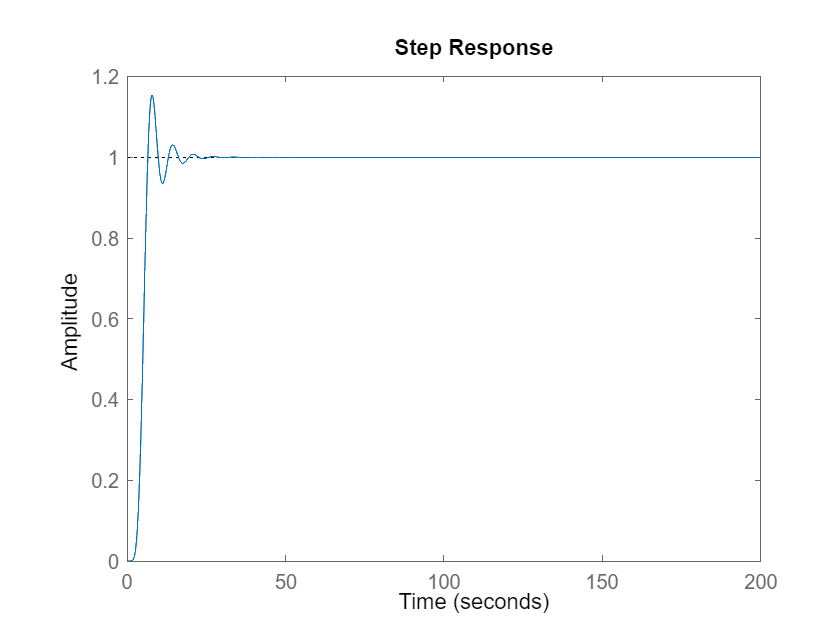

step(sys3)

From plot:

t2p,%overshoot,rise time, settling time

datp(3).t2p=7.76;
datp(3).ov=(1.15-1)*100;
datp(3).rt=6.42;
datp(3).st=11.8;

Data visualisation

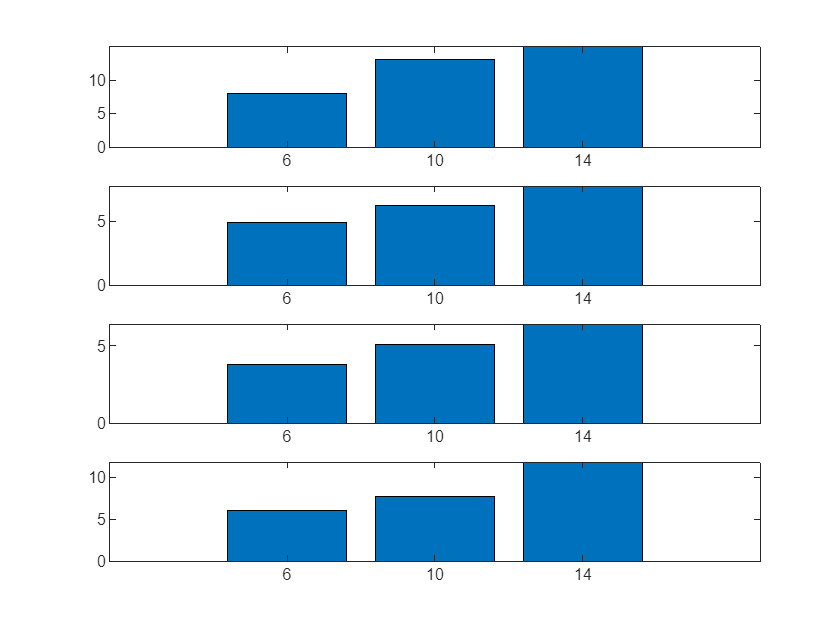

for i=1:3
vis(1,i)=datp(i).ov;
vis(2,i)=datp(i).t2p;
vis(3,i)=datp(i).rt;
vis(4,i)=datp(i).st;
end

for i=1:4
subplot(4,1,i)
bar([10,6,14],vis(i,:))
end

## From subplots we can conclude that the higher number of poles the higher the overshoot, rise time, time to peak and settlnig time.

function [sys,P]=geteqpols(n)

theta=zeros(1,n);
rho=zeros(1,n);

theta(1)=0;
rho(1)=1;

for i = 1:n-1
theta(i+1)=(2*i*pi/n);
rho(i+1)=1;
end 
K = 1;
[x,y]=pol2cart(theta,rho);
for i=1:length(x)
P(i)=x(i)+y(i)*1i;
end
Z=[];
sys = zpk(Z,P,K);

end
